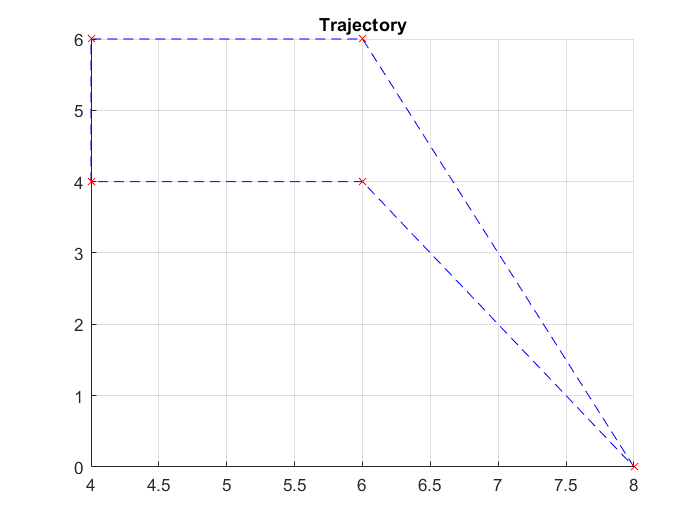

clear all;
close all;

%Coordinates
%start_end_pos=[8 0 0];
%coordinate=[[6 6]; [5 6 ]; [5 5 ]; [6 5];];

%Find Coordinates of edges and generate trajectory. 

coordinate=[8 6 4 4 6 8; 0 6 6 4 4 0];
no_of_samples=1000; 

%trajectory 
[q, qd, qdd, tvec, pp] = trapveltraj(coordinate, no_of_samples);

figure;
hold on;
grid on;
title("Trajectory");
plot(q(1,:),q(2,:),'--b',coordinate(1,:),coordinate(2,:),'xr')

%creating two link planar robot 

% Start with a blank rigid body tree model
robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

% Specify arm lengths for the robot arm
l1=5;
l2=5;

% Add |'link1'| body with |'joint1'| joint.
body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

% Add |'link2'| body with |'joint2'| joint.
body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([l1,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

% Add |'tool'| end effector with |'fix1'| fixed joint.
body = rigidBody('tool');
joint = rigidBodyJoint('fix1','fixed');
setFixedTransform(joint, trvec2tform([l2, 0, 0]));
body.Joint = joint;
addBody(robot, body, 'link2');

% Show details of the robot to validate the input properties. The robot
% should have two non-fixed joints for the rigid bodies and a fixed body
% for the end-effector.
showdetails(robot);

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   tool(3)  
   3         tool          fix1         fixed            link2(2)   
--------------------


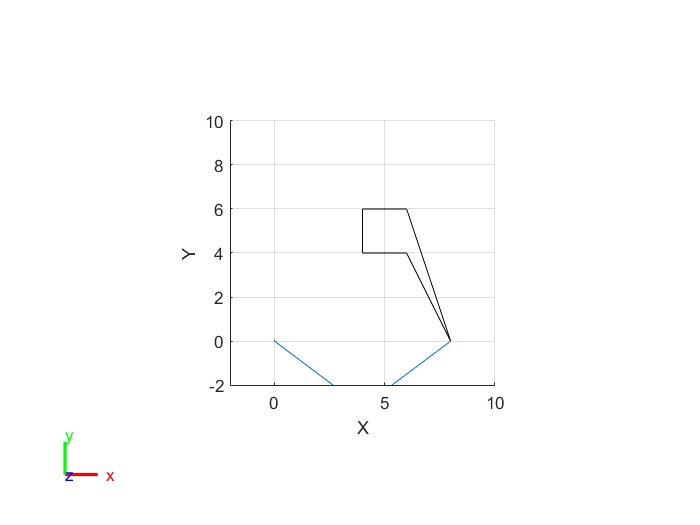

% Pre-allocate configuration solutions as a matrix |qs|.
count=length(tvec);
q0 = homeConfiguration(robot);
ndof = length(q0);
qs = zeros(count, ndof);
x=transpose(q(1,:));
y=transpose(q(2,:));
z=transpose(zeros(size(tvec)));

points=[x,y,z];
% Create the inverse kinematics solver. Because the _xy_ Cartesian points are the
% only important factors of the end-effector pose for this workflow, 
% specify a non-zero weight for the fourth and fifth elements of the 
% |weight| vector. All other elements are set to zero.

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 0];
endEffector = 'tool';

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    % Solve for the configuration satisfying the desired end effector
    % position
    point = points(i,:);
    
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;
    % Start from prior solution
    qInitial = qSol;
end

figure
show(robot,qs(1,:)');
view(2)
ax = gca;
ax.Projection = 'orthographic';
hold on
plot(points(:,1),points(:,2),'k')
axis([-2 10 -2 10])

framesPerSecond = 15;
r = rateControl(framesPerSecond);
for i = 1:count
    show(robot,qs(i,:)','PreservePlot',false);
    drawnow
    waitfor(r);
end


%variables for further calculation
density =1;
g=9.8;

m1=density*l1;
m2=density*l2;
%angular velocity
w_1=zeros(2,no_of_samples);

prev_w1=0;
prev_w2=0;

%angular accelaration
a_acc=zeros(2,no_of_samples);

%centripetal forces/torques
ctp_f=zeros(2,no_of_samples);

%coriolis forces/torques
crl_f=zeros(2,no_of_samples);

%gravity forces/torques
grv_f=zeros(2,no_of_samples);

%inertial forces/torques
int_f=zeros(2,no_of_samples);

%joint forces/torques
joint_f=zeros(2,no_of_samples);

for i=1:no_of_samples
    
    %end effector position
    x2=q(1,i);
    y2=q(2,i);
    
    %end effector velocity
    Vx=qd(1,i);
    Vy=qd(2,i);
    
    %inverse kinematics
    theta_2= acos((x2^2 + y2^2 - l1^2 - l2^2)/(2*l1*l2));
    theta_1=atan2(y2,x2) - atan2((l2*sin(theta_2)),(l1 + l2*cos(theta_2)));
    
    %forward kinematics
    x1 = l1*cos(theta_1);
    y1 = l1*sin(theta_1);
    
    
    x2 = x1+(l2*cos(theta_2+theta_1));
    y2 = y1+(l2*sin(theta_2+theta_1));

    %jarcobian matrix
    jacobian = [[-(l1*sin(theta_1))-(l2*sin(theta_1+theta_2)), -(l1*sin(theta_1+theta_2))];
            [ (l1*cos(theta_1))+(l2*cos(theta_1+theta_2)),  (l2*cos(theta_1+theta_2))]];
    
    %angular velocity
    w = pinv(jacobian)*[Vx; Vy];

    w1 = w(1,1);
    w2 = w(2,1); 
    w_1(1,i)=w1;
    w_1(2,i)=w2;
    
    %angular accelaration
    a_acc1=w1-prev_w1;
    a_acc2=w2-prev_w2;
    a_acc(1,i)=a_acc1;
    a_acc(2,i)=a_acc2;
    
    %christoffel symbols
    %c111=c112=c212=c122=c222=0
    %c211=c121=c221=-0.5*m2*l1*l2*sin(q2)
    
    c221=-0.5*m2*l1*l2*sin(theta_2);
    
    C = [[0 c221];[0 0]]*[w1^2; w2^2];
    ctp_f1= C(1,1);
    ctp_f2= C(2,1);
    ctp_f(1,i)=ctp_f1;
    ctp_f(2,i)=ctp_f2;
    
    %coriolis torques
    crl_f1=-1*m2*l1*l2*sin(theta_2)*w1*w2;
    crl_f2=0;
    crl_f(1,i)=crl_f1;
    crl_f(2,i)=crl_f2;
    
    %gravity torques
    grv_f1=0.5*m1*g*l1*cos(theta_1)+m2*g*(l1*cos(theta_1)+0.5*l2*cos(theta_1+theta_2));
    grv_f2=0.5*m2*g*l2*cos(theta_1+theta_2);
    grv_f(1,i)=grv_f1;
    grv_f(2,i)=grv_f2;
    
    %inertial torques
    M = [[ (m1*(l1^2)/3) + m2*((l1^2)+(l2^2/3)+(l1*l2*cos(theta_2))) m2*(((l2^2)/3)+(l1*l2*cos(theta_2)/2))];
        [ m2*((l2^2/3)+(l1*l2*cos(theta_2)/2))                                                (m2*(l2^2)/3)]];
    
    I=M*[a_acc1; a_acc2];
    int_f1=I(1,1);
    int_f2=I(2,1);
    int_f(1,i)=int_f1;
    int_f(2,i)=int_f2;

    %joint torques
    j1=ctp_f1+crl_f1+grv_f1+int_f1;
    j2=ctp_f2+ctp_f2+grv_f2+int_f2;
    joint_f(1,i)=j1;
    joint_f(2,i)=j2;
    
    %animate
    
end



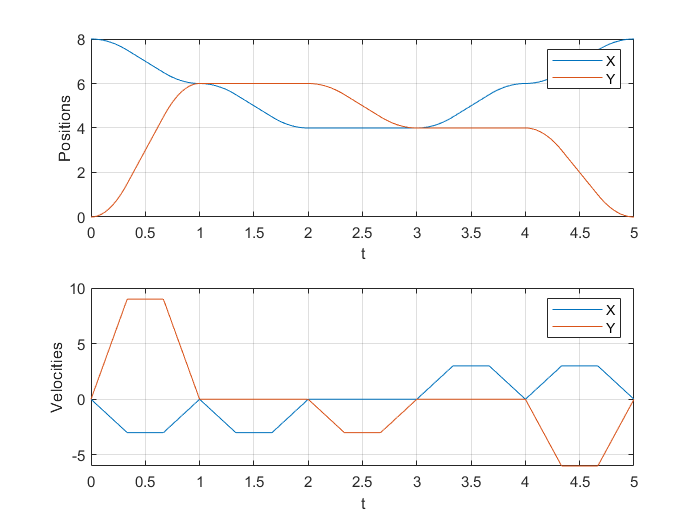

%generating figures

figure;

subplot(2,1,1)
plot(tvec, q)
grid on
xlabel('t')
ylabel('Positions')
legend('X','Y')

subplot(2,1,2)
plot(tvec, qd)
grid on
xlabel('t')
ylabel('Velocities')
legend('X','Y')

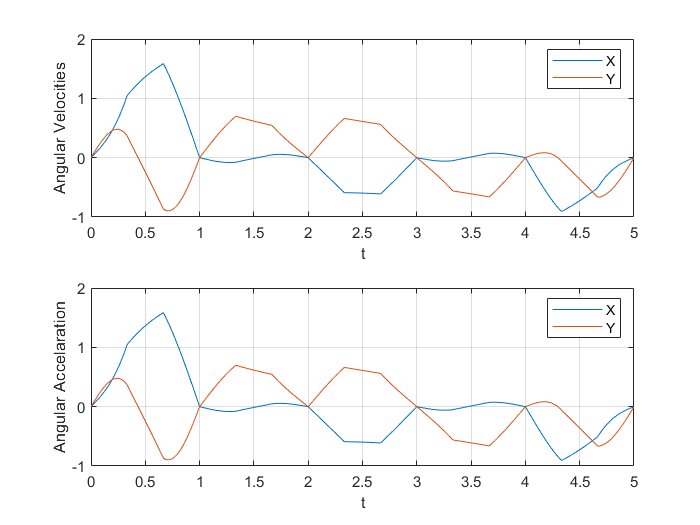


figure;

subplot(2,1,1)
plot(tvec, w_1)
grid on
xlabel('t')
ylabel('Angular Velocities')
legend('X','Y')

subplot(2,1,2)
plot(tvec, a_acc)
grid on
xlabel('t')
ylabel('Angular Accelaration')
legend('X','Y')

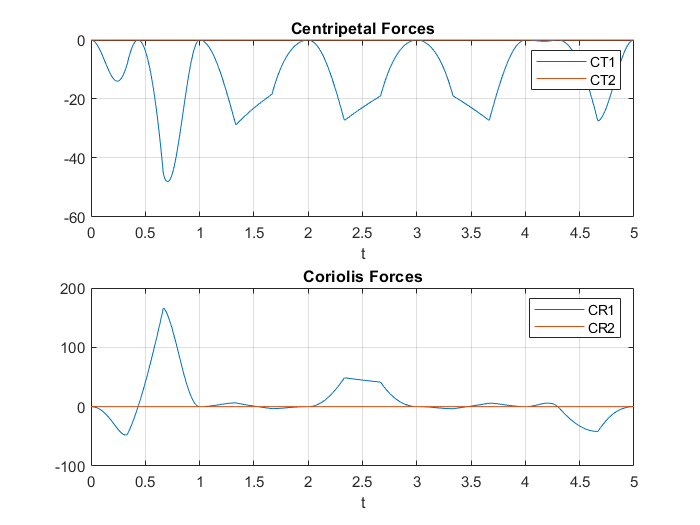

figure;

subplot(2,1,1)
plot(tvec, ctp_f)
grid on
xlabel('t')
title('Centripetal Forces')
legend('CT1','CT2')

subplot(2,1,2)
plot(tvec, crl_f)
grid on
xlabel('t')
title('Coriolis Forces')
legend('CR1','CR2')

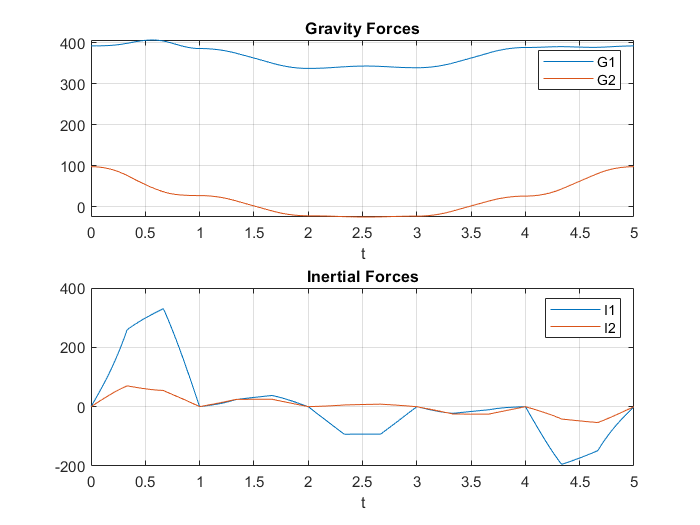


figure;

subplot(2,1,1)
plot(tvec, grv_f)
grid on
xlabel('t')
title('Gravity Forces')
legend('G1','G2')

subplot(2,1,2)
plot(tvec, int_f)
grid on
xlabel('t')
title('Inertial Forces')
legend('I1','I2')

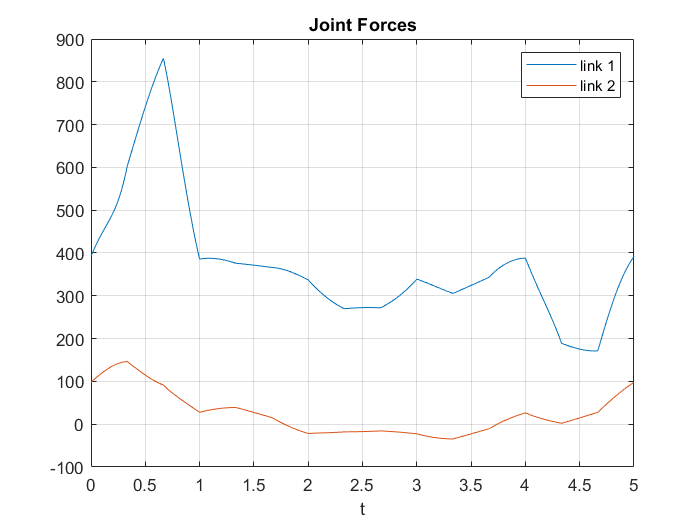

figure;

plot(tvec, joint_f)
grid on
xlabel('t')
title('Joint Forces')
legend('link 1','link 2')